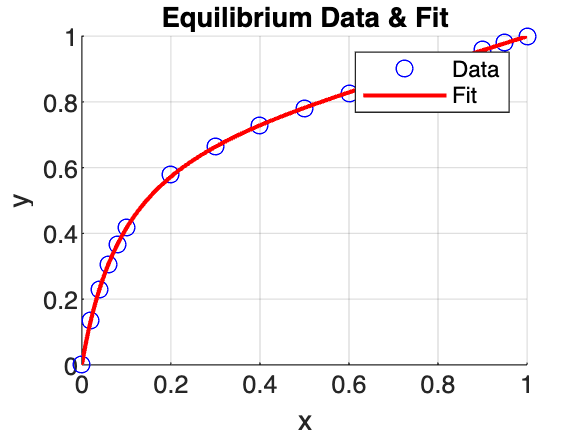

%% binary_distillation.m
% Binary Distillation with Reflux Control and Energy Optimization
clear; clc; close all;

%% Equilibrium data & fit
x_data = [0 0.02 0.04 0.06 0.08 0.10 0.20 0.30 0.40 0.50 0.60 0.70 0.80 0.90 0.95 1.00];
y_data = [0 0.134 0.23 0.304 0.365 0.418 0.579 0.665 0.729 0.779 0.825 0.87 0.915 0.958 0.979 1.00];
model   = @(p,x) (p(1)*x) ./ (1 + p(2)*x + p(3)*x.^2);
params0 = [1,1,1];
opts    = optimoptions('lsqcurvefit','Display','off');
params  = lsqcurvefit(model, params0, x_data, y_data, [], [], opts);
a = params(1); b = params(2); c = params(3);
yeq = @(x) (a*x) ./ (1 + b*x + c*x.^2);

% Plot equilibrium
figure(1); clf;
scatter(x_data,y_data,'bo','DisplayName','Data'); hold on;
xfit = linspace(0,1,200);
plot(xfit, yeq(xfit),'r-','LineWidth',1.5,'DisplayName','Fit');
xlabel('x'); ylabel('y');
title('Equilibrium Data & Fit');
legend; grid on;

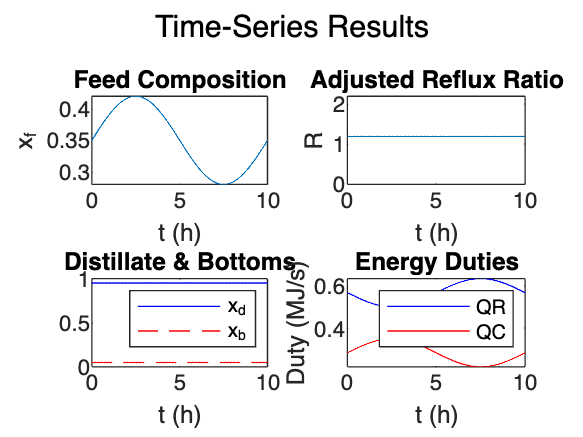


%% Time settings
t         = linspace(0,10,1001);  % h
xf        = 0.35 + 0.07*sin((2*pi/10)*t);
xd_target = 0.95; xb = 0.05;
n         = numel(t);

% Preallocate
stages = nan(1,n); xd = nan(1,n);
QR = nan(1,n); QC = nan(1,n);
R_used = nan(1,n);

% Constants
mF       = 1;              % kg/s
L        = 8.55e5;         % J/kg
N_target = 10;             % design stages
Rmin     = 1.2; Rmax = 5;  % reflux bounds

%% Energy‐minimizing simulation loop
for i = 1:n
    xi = xf(i);
    R_obj = @(Rtry) stage_penalty(Rtry, xd_target, xb, yeq, N_target);
    R_used(i) = fminbnd(R_obj, Rmin, Rmax);
    stages(i) = compute_stages(xd_target, xb, yeq, R_used(i));
    D = (mF*(xi - xb)) / (xd_target - xb);
    B = mF - D;
    xd(i) = xd_target;
    QC(i) = D * L;
    QR(i) = B * L;
end

%% Plot time‐series
figure(2); clf;
subplot(2,2,1);
  plot(t, xf);
  xlabel('t (h)'); ylabel('x_f'); title('Feed Composition');
subplot(2,2,2);
  plot(t, R_used);
  xlabel('t (h)'); ylabel('R'); title('Adjusted Reflux Ratio');
subplot(2,2,3);
  plot(t, xd,'b', t, xb*ones(size(t)),'--r');
  xlabel('t (h)'); legend('x_d','x_b'); title('Distillate & Bottoms');
subplot(2,2,4);
  plot(t, QR/1e6,'-b', t, QC/1e6,'-r');
  xlabel('t (h)'); ylabel('Duty (MJ/s)');
  legend('QR','QC'); title('Energy Duties');
sgtitle('Time‐Series Results');


%% Export results
T = table(t', xf', R_used', xd', xb*ones(n,1), stages', QR', QC', ...
    'VariableNames',{'t_h','x_f','R','x_d','x_b','Stages','QR_J','QC_J'});
writetable(T,'distillation_final_results.xlsx');
fprintf('Total QR: %.2e J\n', trapz(t,QR));

Total QR: 5.70e+06 J


fprintf('Total QC: %.2e J\n', trapz(t,QC));

Total QC: 2.85e+06 J


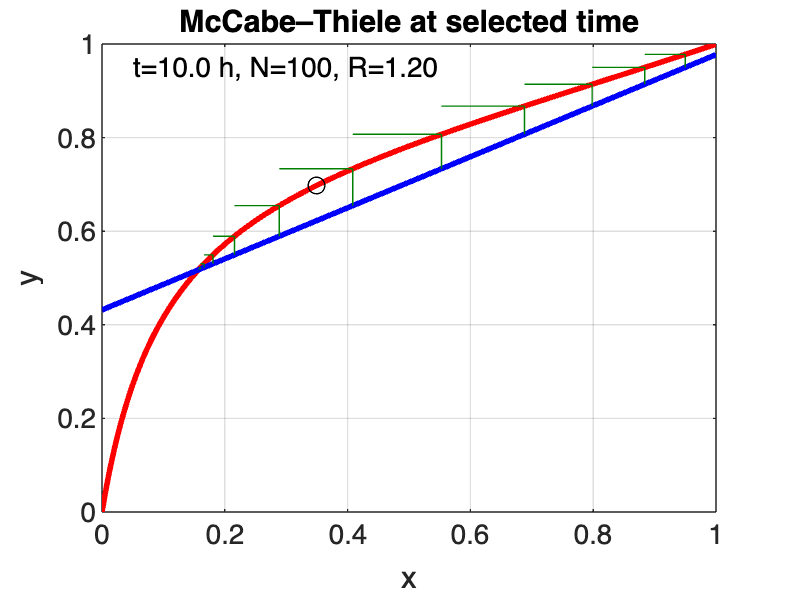


%% Dynamic McCabe–Thiele with robust fzero
figure(3); clf;
darkGreen = [0 0.5 0];

for k = 1:100:1001
    clf;
    Ri   = R_used(k);
    xi   = xf(k);
    xd_k = xd(k);

    % Plot equilibrium & operating
    x_vals = linspace(0,1,200);
    plot(x_vals, yeq(x_vals),'r','LineWidth',2); hold on;
    plot(x_vals, (Ri./(Ri+1)).*x_vals + xd_k./(Ri+1), 'b','LineWidth',2);

    % q‐line & feed
    q  = 1;
    xq = linspace(xb, xd_k, 200);
    plot(xq, (q./(q-1)).*xq - xi./(q-1), '--k');
    plot(xi, yeq(xi), 'ko','MarkerSize',6);

    % Staircase
    x = xd_k;
    N = 0;
    maxSteps = 100;
    while x > xb && N < maxSteps
        y = (Ri/(Ri+1))*x + xd_k/(Ri+1);

        % Unbracketed root solve
        try
            x_next = fzero(@(xx) yeq(xx) - y, x - 0.01);
        catch
            % fallback small step
            x_next = x - 0.01;
        end

        % Clamp to [xb, x]
        x_next = max(xb, min(x_next, x));

        % Plot the legs
        plot([x x],        [y      yeq(x)],   'Color', darkGreen);
        plot([x x_next], [yeq(x) yeq(x)], 'Color', darkGreen);

        x = x_next;
        N = N + 1;
    end

    text(0.05,0.95, sprintf('t=%.1f h, N=%d, R=%.2f', t(k), N, Ri), ...
         'Units','normalized','FontSize',10);
    xlabel('x'); ylabel('y'); grid on;
    title('McCabe–Thiele at selected time');
    % pause(0.3);
end


%% Analytical R_min
xF_const = 0.35;
slope = (xd_target - yeq(xF_const)) / (xd_target - xF_const);
R_min_est = slope / (1 - slope);
fprintf('Analytical R_min: %.2f\n', R_min_est);

Analytical R_min: 0.72



%% Helper functions

function N = compute_stages(xd, xb, yeq, R)
    N = 0; x = xd;
    maxSteps = 100;
    while x > xb && N < maxSteps
        y = (R/(R+1))*x + xd/(R+1);
        try
            x = fzero(@(xx) yeq(xx) - y, x - 0.01);
        catch
            x = x - 0.01;
        end
        x = max(xb, x);
        N = N + 1;
    end
end

function cost = stage_penalty(R, xd, xb, yeq, Nmin)
    N = compute_stages(xd, xb, yeq, R);
    if N < Nmin
        cost = 1e6 + (Nmin - N)*1e4;
    else
        D = 0.5; B = 0.5; L = 8.55e5;
        cost = B*L + D*L + R*1e3;
    end
end

